clear all; clc;close all;

% Parameterse
G =  6.674e-11;% Gravitational constant in arbitrary units
m1 = 1.989e30; % Mass of body sun
m2 = 5.972e24; % Mass of body earth
m3 = 6.39e23; % Mass of body mars
R12 = 1.496e11;
R13 = 2.279e11;
M = [m1 m2 m3];

v12 = sqrt(G*m1/R12);
v13 = sqrt(G*m1/R13);

beta = 2.0;

% Initial
% positions and velocities [x1, y1, x2, y2, x3, y3, vx1, vy1, vx2, vy2, vx3, vy3]

% Initial conditions for figure-eight orbit
%
IC_Y = [ ...
     0, 0, ... % x1, y1
     R12,0 ... % x2, y2
     R13,0 ... % x3, y3
];   

IC_Yp = [ ...
     0, 0,   ... % vx1, vy1
     0, v12, ... % vx2, vy2
     0, v13  ... % vx3, vy3
];   


%}

% Time span
tspan = [0, 31536000000];

fns=@(t, Y,Yp) threeBodyODE(t, Y, Yp, G, m1, m2, m3,beta,true);
frk=@(t, Y) threeBodyODE(t, Y(1:(end/2)), Y((end/2+1):end), G, m1, m2, m3,beta,false);

options = odeset('RelTol', 1e-10, 'AbsTol', 1e-10);
tprev = tic;
[trk, Yrk] = ode89(frk, tspan, [IC_Y,IC_Yp]);
trkc = toc(tprev)

trkc = 0.4282



x0 = -nthroot(2,3)/(2-nthroot(2,3));
x1 = 1/(2-nthroot(2,3));
y0 = -nthroot(2,5)/(2-nthroot(2,5));
y1 = 1/(2-nthroot(2,5));

D = [x1*y1 x0*y1 x1*y1 x1*y0 x0*y0 x1*y0 x1*y1 x0*y1 x1*y1 0];
C = .5*[D(1) D(1)+D(2) D(2)+D(3) D(3)+D(4) D(4)+D(5) D(5)+D(6) D(6)+D(7) D(7)+D(8) D(8)+D(9) D(9)];
% C = [2/3 -2/3 1];
% D = [7/24 3/4 -1/24];
% C = [1 1-nthroot(2,3) 1-nthroot(2,3) 1]/(2*(2-nthroot(2,3)));
% D = [1 -nthroot(2,3) 1 0]/(2-nthroot(2,3));
% C = [1];
% D = [1];
% W = [
%     -0.161582374150097e1
%     -0.244699182370524e1
%     -0.716989419708120e-2
%      0.244002732616735e1
%      0.157739928123617e0
%      0.182020630970714e1
%      0.104242620869991e1]
% W = [
% 0.227738840094906E-1
% 0.252778927322839E1
% -0.719180053552772E-1
% 0.536018921307285E-2
% -0.204809795887393E1
% 0.107990467703699E0
% 0.130300165760014E1
% ];

dt = 1e6;
IC_Ypns =IC_Yp-dt*fns(0,IC_Y,IC_Yp);

tprev = tic;
[tns,Yns,Ypns] = NSympCD(fns,tspan,IC_Y,IC_Ypns,dt,4); 
tnsc = toc(tprev)

tnsc = 1.6676

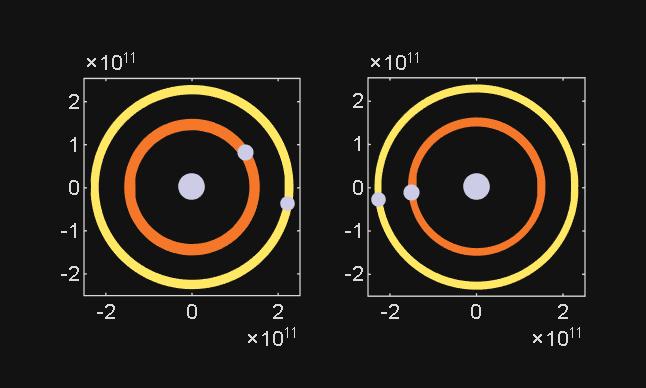

% Plot and animate

Tstart = max(tns(2),trk(2));
SF = 1.1;
NP = 3;

subplot(1,2,1)
xr = [min(Yns(:,[1:2:2*NP]+0),[],'all') max(Yns(:,[1:2:2*NP]+0),[],'all')];
yr = [min(Yns(:,[1:2:2*NP]+1),[],'all') max(Yns(:,[1:2:2*NP]+1),[],'all')];
HP1 = plot(Yns(tns<=Tstart,[1:2:2*NP]+0),Yns(tns<=Tstart,[1:2:2*NP]+1),'LineWidth',2.5);
hold on
SP1 = scatter(Yns(tns==max(tns(tns<=Tstart)),[1:2:2*NP]+0),Yns(tns==max(tns(tns<=Tstart)),[1:2:2*NP]+1),100*log(M).^5/norm(log(M).^5,10),[.8 .8 .9],'o','filled');
view([0 90])
axis equal
xlim(SF*xr)
ylim(SF*yr)
subplot(1,2,2)
xr = [min(Yrk(:,[1:2:2*NP]+0),[],'all') max(Yrk(:,[1:2:2*NP]+0),[],'all')];
yr = [min(Yrk(:,[1:2:2*NP]+1),[],'all') max(Yrk(:,[1:2:2*NP]+1),[],'all')];
HP2 = plot(Yrk(trk<=Tstart,[1:2:2*NP]+0),Yrk(trk<=Tstart,[1:2:2*NP]+1),'LineWidth',2.5);
hold on
SP2 = scatter(Yrk(trk==max(trk(trk<=Tstart)),[1:2:2*NP]+0),Yrk(trk==max(trk(trk<=Tstart)),[1:2:2*NP]+1),100*log(M).^5/norm(log(M).^5,10),[.8 .8 .9],'o','filled');
view([0 90])
axis equal
xlim(SF*xr)
ylim(SF*yr)

for t_r=linspace(Tstart,tspan(2),100)

set(HP1,{'XData'},mat2cell(Yns(tns<=t_r,[1:2:2*NP]+0)',ones(1,NP)));
set(HP1,{'YData'},mat2cell(Yns(tns<=t_r,[1:2:2*NP]+1)',ones(1,NP)));
set(SP1,'XData',Yns(tns==max(tns(tns<=t_r)),[1:2:2*NP]+0));
set(SP1,'YData',Yns(tns==max(tns(tns<=t_r)),[1:2:2*NP]+1));

set(HP2,{'XData'},mat2cell(Yrk(trk<=t_r,[1:2:2*NP]+0)',ones(1,NP)));
set(HP2,{'YData'},mat2cell(Yrk(trk<=t_r,[1:2:2*NP]+1)',ones(1,NP)));
set(SP2,'XData',Yrk(trk==max(trk(trk<=t_r)),[1:2:2*NP]+0));
set(SP2,'YData',Yrk(trk==max(trk(trk<=t_r)),[1:2:2*NP]+1));

drawnow;
end


% Function to compute the derivatives for the 3-body problem
function Ypp = threeBodyODE(t, Y, Yp, G, m1, m2, m3, beta,rknsc)
    % Unpack variables
    
x1  = Y(1);  y1  = Y(2);
    x2  = Y(3);  y2  = Y(4);
    x3  = Y(5);  y3  = Y(6);
    vx1 = Yp(1); vy1 = Yp(2);
    vx2 = Yp(3); vy2 = Yp(4);
    vx3 = Yp(5); vy3 = Yp(6);

    % Compute distances between bodies
    dx12 = x2 - x1; dy12 = y2 - y1; r12 = sqrt(dx12^2 + dy12^2);
    dx13 = x3 - x1; dy13 = y3 - y1; r13 = sqrt(dx13^2 + dy13^2);
    dx23 = x3 - x2; dy23 = y3 - y2; r23 = sqrt(dx23^2 + dy23^2);

    % Gravitational forces between the bodies
    F12_mag = G * m1 * m2 / r12^beta;
    F13_mag = G * m1 * m3 / r13^beta;
    F23_mag = G * m2 * m3 / r23^beta;

    theta12 = atan2(dy12, dx12); % Angle between the two bodies
    theta13 = atan2(dy13, dx13); % Angle between the two bodies
    theta23 = atan2(dy23, dx23); % Angle between the two bodies

    % Decompose forces into x and y components
    F12_x = F12_mag * cos(theta12); F12_y = F12_mag * sin(theta12);
    F13_x = F13_mag * cos(theta13); F13_y = F13_mag * sin(theta13);
    F23_x = F23_mag * cos(theta23); F23_y = F23_mag * sin(theta23);

    % Accelerations for each body
    ax1 = (F12_x + F13_x) / m1;
    ay1 = (F12_y + F13_y) / m1;
    ax2 = (-F12_x + F23_x) / m2;
    ay2 = (-F12_y + F23_y) / m2;
    ax3 = (-F13_x - F23_x) / m3;
    ay3 = (-F13_y - F23_y) / m3;


    if rknsc == true
    Ypp = [ax1, ay1, ax2, ay2, ax3, ay3];
    else
    Ypp = [vx1; vy1; vx2; vy2; vx3; vy3; ax1; ay1; ax2; ay2; ax3; ay3];
    end

end


function [t,Y,Yp] = NSympCD(ode,tspan,Y0,Yp0,dt,order)
% [t,Y,Yp] = ode(t,Y,Yp)
% d corosponds to Yp
% c corosponds to Y

x0 = -nthroot(2,3)/(2-nthroot(2,3));
x1 = 1/(2-nthroot(2,3));
y0 = -nthroot(2,5)/(2-nthroot(2,5));
y1 = 1/(2-nthroot(2,5));

switch order
    case 1
D = 1;
C = 1;
    case 2
D = [1 0];
C = [1 1]*.5;
    case 3
D = [7/24 3/4 -1/24];
C = [2/3 -2/3 1];
    case 4
D = [x1 x0 x1 0];
C = [x1 x0+x1 x0+x1 x1]*.5;
    case 10
D = [x1*y1 x0*y1 x1*y1 x1*y0 x0*y0 x1*y0 x1*y1 x0*y1 x1*y1 0];
C = .5*[D(1) D(1)+D(2) D(2)+D(3) D(3)+D(4) D(4)+D(5) D(5)+D(6) D(6)+D(7) D(7)+D(8) D(8)+D(9) D(9)];
    otherwise
D = 1;
C = 1;
end

numsteps = round((tspan(2)-tspan(1))/dt);
t = tspan(1)*ones(1,numsteps);
Yp(1,:) = Yp0;
Y( 1,:) = Y0;
for i = 2:numsteps
    t(i) = t(i-1) + dt;
    Yp(i,:) = Yp(i-1,:);
    Y( i,:) = Y( i-1,:);
    for j=1:order
    Yp(i,:) = Yp(i,:)+D(j).*ode(t,Y(i,:),Yp(i,:))*dt;
    Y (i,:) = Y (i,:)+C(j).*Yp(i,:)*dt;
    end
end
end





function [t,Y,Yp] = NSympW(ode,tspan,y0,yp0,dt,W)
d=[];
c=[];
m = numel(W);
w0 = 1-2*sum(W);
d(2*m+2) = 0;
d(m+1) = w0;
d(1:m) = W(m:-1:1);
d(2*m+2-(1:m)) = W(m:-1:1);
c(m+1)=.5*(w0+W(1));
c(1) = .5*W(m);
c(2*m+2) = c(1);
c(2:m) = .5*(W(m:-1:2)+W((m:-1:2)-1));
c((2*m:-1:m+1)+1) = c(2:(m+1));

[t,Y,Yp] = NSympCD(ode,tspan,y0,yp0,dt,c,d);
end